# Question 1

### a) Construct the matrix A in MATLAB for n = 10. Hint: use the built-in functions eye and circshift to do this.

n = 10;
A = eye(n);
Y1 = circshift(A,3);
Y2 = circshift(A,3,2);
A = (Y1 + Y2)/2

A =          0         0         0    0.5000         0         0         0    0.5000         0         0
         0         0         0         0    0.5000         0         0         0    0.5000         0
         0         0         0         0         0    0.5000         0         0         0    0.5000
    0.5000         0         0         0         0         0    0.5000         0         0         0
         0    0.5000         0         0         0         0         0    0.5000         0         0
         0         0    0.5000         0         0         0         0         0    0.5000         0
         0         0         0    0.5000         0         0         0         0         0    0.5000
    0.5000         0         0         0    0.5000         0         0         0         0         0
         0    0.5000         0         0         0    0.5000         0         0         0         0
         0         0    0.5000         0         0         0    0.5000         0       

### b) Plot (i) the maximum and (ii) the second lowest number in the matrix A^N as a function of N (n is still 10). Plot both curves on the same figure.

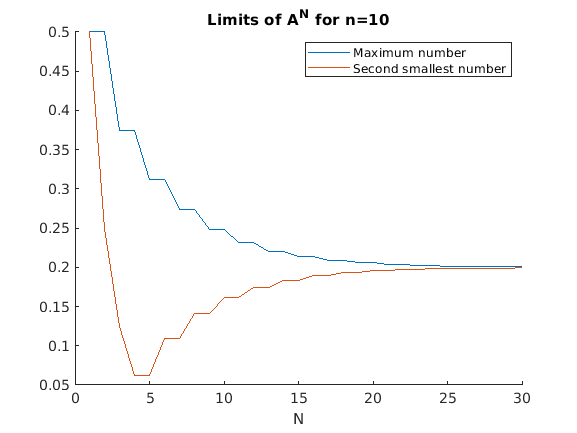

N_max = 30;
plot_i = zeros(1, N_max);
plot_ii = zeros(1, N_max);

for i=1:N_max
    A2 = A^i;
    
    % max number
    plot_i(1, i) = max(max(A2));
    
    % second lowest number
    A2 = sort(A2(:));
    
    x = 1;
    lowest = A2(x);
    second_lowest = lowest;
    while second_lowest == lowest
        x = x + 1;
        second_lowest = A2(x);
    end
    plot_ii(1, i) = second_lowest;
end
N = 1:1:N_max;
figure
hold on;
plot(N, plot_i)
plot(N, plot_ii)
xlabel('N')
legend('Maximum number','Second smallest number')
title('Limits of A^N for n=10')

saveas(gcf,'q1b.jpg')

plot_i(1, N_max)

ans = 0.2007

### c) Deduce the limits

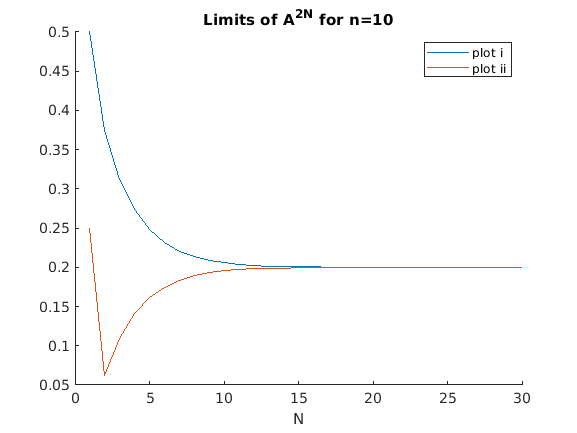

n = 10;
N_max = 30;
plot_i = zeros(1, N_max);
plot_ii = zeros(1, N_max);

for i=1:N_max
    A2 = A^(2*i);
    
    % max number
    plot_i(1, i) = max(max(A2));
    
    % second lowest number
    A2 = sort(A2(:));
    
    x = 1;
    lowest = A2(x);
    second_lowest = lowest;
    while second_lowest == lowest
        x = x + 1;
        second_lowest = A2(x);
    end
    plot_ii(1, i) = second_lowest;
end
N = 1:1:N_max;
figure
hold on;
plot(N, plot_i)
plot(N, plot_ii)
xlabel('N')
legend('plot i','plot ii')
title('Limits of A^{2N} for n=10')
saveas(gcf,'q1c.jpg')

plot_i(1, N_max)

ans = 0.2000

plot_ii(1, N_max)

ans = 0.2000

A^(200)

ans =     0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0
         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000
    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0
         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000
    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0
         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000
    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0
         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000
    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0
         0    0.2000         0    0.2000         0    0.2000         0    0.2000     

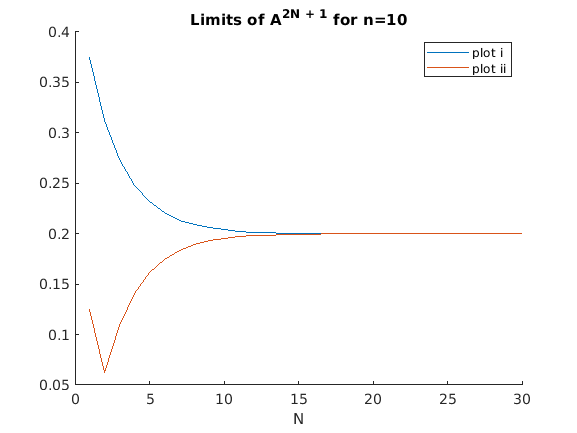

N_max = 30;
plot_i = zeros(1, N_max);
plot_ii = zeros(1, N_max);

for i=1:N_max
    A2 = A^((2*i) + 1);
    
    % max number
    plot_i(1, i) = max(max(A2));
    
    % second lowest number
    A2 = sort(A2(:));
    
    x = 1;
    lowest = A2(x);
    second_lowest = lowest;
    while second_lowest == lowest
        x = x + 1;
        second_lowest = A2(x);
    end
    plot_ii(1, i) = second_lowest;
end
N = 1:1:N_max;
figure
hold on;
plot(N, plot_i)
plot(N, plot_ii)
xlabel('N')
legend('plot i','plot ii')
title('Limits of A^{2N + 1} for n=10')
saveas(gcf,'q1c2.jpg')

A^((2*N_max) + 1)

ans =          0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000
    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0
         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000
    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0
         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000
    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0
         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000
    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0
         0    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0.2000
    0.2000         0    0.2000         0    0.2000         0    0.2000         0    0

plot_i(1, N_max)

ans = 0.2000

plot_ii(1, N_max)

ans = 0.2000

### **d) Deduce the non-zero values**

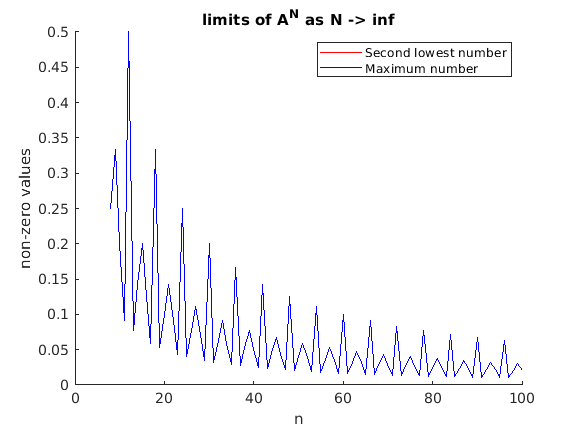

max_n = 100;
plot_n = zeros(1, max_n);
plot_n2 = zeros(1, max_n);
N_max = 50000;

for n=8:max_n
    A = eye(n);
    Y1 = circshift(A,3);
    Y2 = circshift(A,3,2);
    A = (Y1 + Y2)/2;

    A2 = A^N_max;
    
    % max number
    max_num = max(max(A2));
    
    % second lowest number
    A2 = sort(A2(:));
    
    x = 1;
    lowest = A2(x);
    second_lowest = lowest;
    while second_lowest == lowest
        x = x + 1;
        second_lowest = A2(x);
    end
    lowest_num = second_lowest;
    
    % get limits
    plot_n(1, n) = max_num;
    plot_n2(1, n) = lowest_num;
end

N = 8:max_n;

figure
hold on;
plot(N, plot_n2(1, [8:max_n]), 'r')
plot(N, plot_n(1, [8:max_n]), 'b')
legend("Second lowest number", "Maximum number")
xlabel('n')
ylabel('non-zero values')
title('limits of A^N as N -> inf')
saveas(gcf,'q1d.jpg')

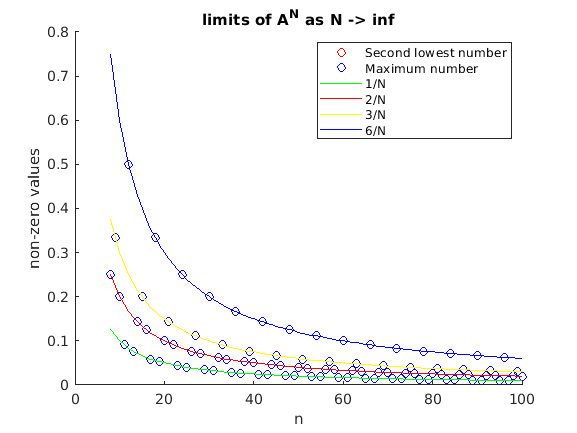


figure
hold on;
scatter(N, plot_n2(1, [8:max_n]), 'r')
scatter(N, plot_n(1, [8:max_n]), 'b')
y1 = 1 ./ N;
y2 = 2 ./ N;
y3 = 3 ./ N;
y6 = 6 ./ N;
plot(N, y1, 'g');
plot(N, y2, 'r');
plot(N, y3, 'y');
plot(N, y6, 'b');

legend("Second lowest number", "Maximum number", ...
    "1/N", "2/N", "3/N", "6/N")
xlabel('n')
ylabel('non-zero values')
title('limits of A^N as N -> inf')
saveas(gcf,'q1d2.jpg')